clear all; close all;

## Load data

load("bonus2data_v2\nb14&63_-6&77.mat");                       % load data
X = signal;                                             % 6-channel received signals

## waveform

c = 340;
[N,nSensors] = size(X);

## Array setup

n_source = 2;                                          % number of sources
r = 0.035;
p = r*[cosd(-150),sind(-150),0;...
    cosd(-90),sind(-90),0;...
    cosd(-30),sind(-30),0;...
    cosd(30),sind(30),0;...
    cosd(90),sind(90),0;...
    cosd(150),sind(150),0];                            % sensor position

## Plot sensor positions

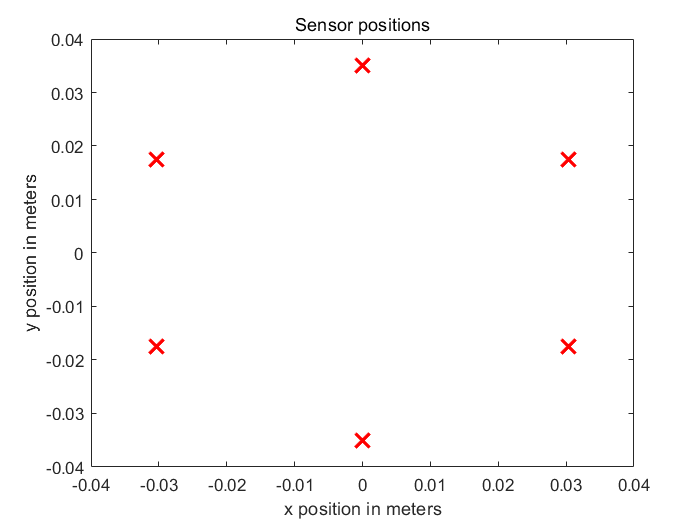

linspec = {'rx','MarkerSize',12,'LineWidth',2};
figure;
plot(p(:,1),p(:,2),linspec{:});
title('Sensor positions');
xlabel('x position in meters');
ylabel('y position in meters');

disp('The six microphones are ready !');

The six microphones are ready !


## DoA estimation (MUSIC)

stride = 1;                                               % determine the angular resolution(deg)
theta = -90:stride:90;                                    % grid
phi = 0:stride:90;

% implement eigen-decomposition and obtain the pseudo spectrum
R_x = (X.'*(X.')')/N;                                     % autocorrelation estimate
[EV,~] = eig(R_x);     
Un = EV(:,1:end-n_source);                                % noise subspace (columns are eigenvectors), size: J*(J-n_source)       

P_sm = zeros(length(theta),length(phi));                  % pseudo music power
for i = 1:length(phi)
    tphi = phi(i);
    
    v = [sind(theta)*cosd(tphi); ...
         -cosd(theta)*cosd(tphi); ...
         ones(size(theta))*sind(tphi)];                   % direction vector
    a_theta = exp(-1j*2*pi*fc/c*p*v);                     % steer vector
    
    % Compute pseudo spectrum for this phi
    P_sm(:,i) = 1./diag(a_theta'*(Un*Un')*a_theta);
end                                                 

## Plot the MUSIC pseudo power spectrum

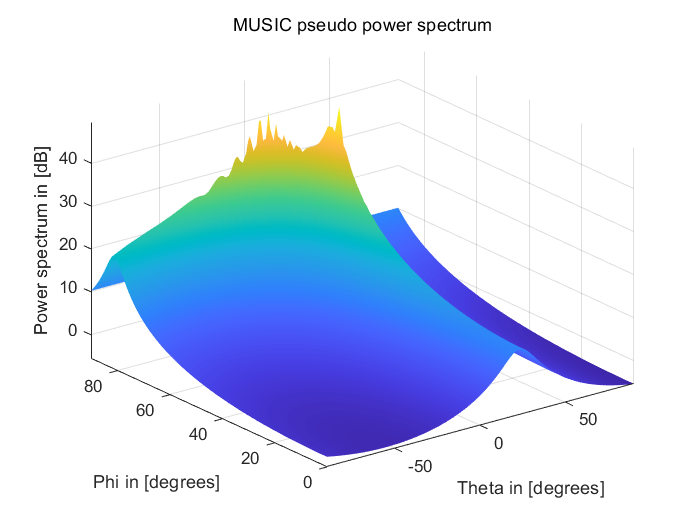

figure();
surf(theta, phi, 10*log10(abs(P_sm.')));
shading interp;
title('MUSIC pseudo power spectrum');
xlabel('Theta in [degrees]');
ylabel('Phi in [degrees]');
zlabel('Power spectrum in [dB]');
grid on; axis tight;
print('nb14&63_-6&77','-depsc','-vector');

## Find the local maximum and visualization

P_local = P_sm;
[px,py] = size(P_local);
P_min = min(min(P_local));

for i = 1:px
    P = P_local(i,:).';
    P_middle = abs(P(2:end-1));
    P_front = abs(P(1:end-2));
    P_back = abs(P(3:end));
    logic_front = (P_middle - P_front)>0;
    logic_back = (P_middle - P_back)>0;
    logic = logic_front & logic_back;
    P_middle(~logic) = P_min;
    P_local(i,:) = [abs(P(1));P_middle;abs(P(end))];
end

for j = 1:py
    P = P_local(:,j);
    P_middle = abs(P(2:end-1));
    P_front = abs(P(1:end-2));
    P_back = abs(P(3:end));
    logic_front = (P_middle - P_front)>0;
    logic_back = (P_middle - P_back)>0;
    logic = logic_front & logic_back;
    P_middle(~logic) = P_min;
    P_local(:,j) = [abs(P(1));P_middle;abs(P(end))];
end

[Idxt1,Idxp1] = find(P_local==max(max(P_local)));
P_local(Idxt1,Idxp1) = 0;
[Idxt2,Idxp2] = find(P_local==max(max(P_local)));

disp(['The desired source DOA with MUSIC is: theta=',num2str(theta(Idxt1)),' deg and phi=',num2str(phi(Idxp1)),' deg']);

The desired source DOA with MUSIC is: theta=14 deg and phi=63 deg


disp(['The interfering DOA with MUSIC is: theta=',num2str(theta(Idxt2)),' deg and phi=',num2str(phi(Idxp2)),' deg']);

The interfering DOA with MUSIC is: theta=-6 deg and phi=77 deg
